clear;clc;

k = 80; % Spring constant
d = -2.5; % Damping ratio
m = 1.5; % Mass in Kg

A = [0 1; (-k/m) (-d/m)]; % Damper ODE
B = [0; 1/m];


## Control Setup

controllability = det(ctrb(A,B))

controllability = -0.4444

K = [6, 13];

% Q = [10, 0;
%     0, 1];
% R = 0.01;
% K = lqr(A,B,Q,R);

fixed_point = [0; 0];
u = @(q) -K*(q-fixed_point);

## Simulate Dynamics

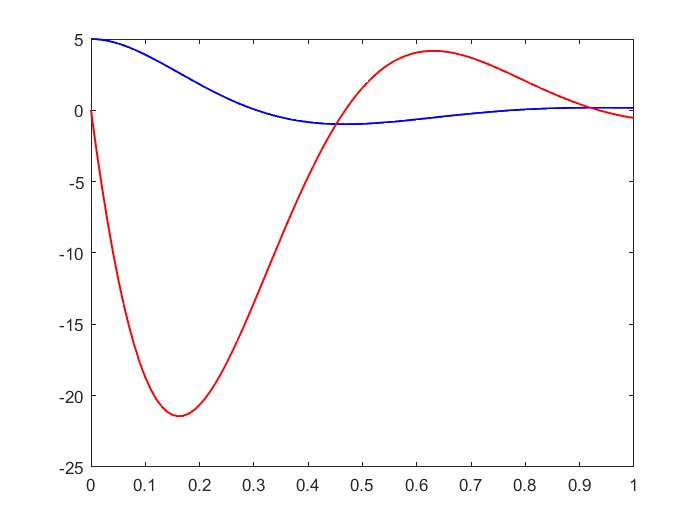

dt = 0.01; T = 1; % Simulation time

x0 = [5; 0]; % Initial conditions

[t,x] = ode45(@(t,x) A*x+B*u(x), 0:dt:T, x0); % Solve ODE at different timesteps
plot(t,x(:,1),'b','LineWidth',1); % Plot position
hold on;
plot(t,x(:,2),'r','LineWidth',1); % Plot velocity